There are currently 3 defined kernel types:

EQ - exponential Quadratic (SE squared exponential)

RQ - Rational Quadratic (alpha=1)

Matern52

These kernels can be added subtracted multiplied and divided

The GP class takes a mean function and a kernel.

it then can be conditioned on data x and y and can then be trained using mean aposteriori HP selection.

f1 = @(x) (6*x(:,1)-2).^2.*sin(12*x(:,2)-4);%.*sin(24*x-1);

x1 = lhsdesign(30,2);
y1 = f1(x1)+normrnd(0*x1(:,1),0*x1(:,1));

%a = means.linear(4)*means.sine(1,3,0,1)
%a = means.sine(1,3,0,1);
a = means.zero();

d = (kernels.Matern52(1,0.2) + kernels.EQ(0.2,0.4))*kernels.RQ(2,1,0.1);
%d = kernels.EQ(1,[1 1])
d.signn = 0;

Z = GP(a,d);

Z1 = Z.condition(x1,y1);

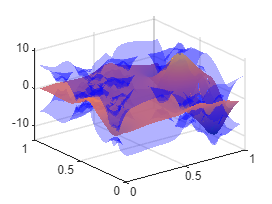

figure
utils.plotSurf(Z1,2,1)

tic
[Z2] = Z1.train();
toc

Elapsed time is 1.032501 seconds.


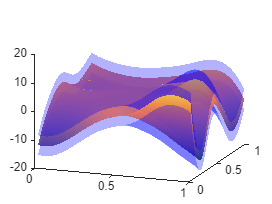

figure
hold on
utils.plotSurf(Z2,2,1)
view(20,20)

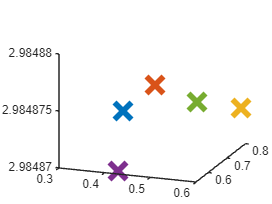

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmax(@BO.maxVAR,Z2);
    plot3(x{i}(1),x{i}(2),R{i},'x','MarkerSize',18,'LineWidth',4)
end
view(20,20)

toc

Elapsed time is 0.298152 seconds.


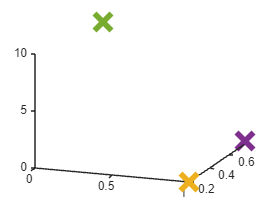

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmin(@BO.EImin,Z2);
    plot3(x{i}(1),x{i}(2),R{i},'x','MarkerSize',18,'LineWidth',4)
end
view(20,20)

toc

Elapsed time is 1.522028 seconds.
